clear

addpath("matlab_functions\")

method = "Analytical";

#### Compute Sensitivity

if strcmpi(method, 'Analytical')
    [Plate, Coil, Sensor] = myModel;
else
    [Plate, Coil, Sensor, Model] = myModel;
    mesh_size = 2; % 1:finest 9:coarsest
end

for freq = [900 225 100 55]
    if strcmpi(method, 'Analytical')
        S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq);
    else
        S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size);
    end
    
    element_centers = Plate.elems_center;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S','element_centers')
end

Compute coil took 2.67 seconds
Compute sensor 1 took 0.41 seconds
Compute sensor 2 took 0.47 seconds
Compute sensor 3 took 0.42 seconds
Compute sensor 4 took 0.50 seconds
Compute sensor 5 took 0.42 seconds
Compute sensor 6 took 0.47 seconds
Compute sensor 7 took 0.41 seconds
Compute sensor 8 took 0.51 seconds
Compute sensor 9 took 0.48 seconds
Compute sensor 10 took 0.51 seconds
Compute sensor 11 took 0.43 seconds
Compute sensor 12 took 0.46 seconds
Compute sensor 13 took 0.44 seconds
Compute sensor 14 took 0.47 seconds
Compute sensor 15 took 0.45 seconds
Compute sensor 16 took 0.45 seconds
Compute sensor 17 took 0.47 seconds
Compute sensor 18 took 0.42 seconds
Compute sensor 19 took 0.48 seconds
Compute sensor 20 took 0.41 seconds
Compute sensor 21 took 0.47 seconds
Compute sensor 22 took 0.43 seconds
Compute sensor 23 took 0.48 seconds
Compute sensor 24 took 0.42 seconds
Compute sensor 25 took 0.43 seconds
Compute sensor 26 took 0.45 seconds
Compute sensor 27 took 0.41 seconds
Comput


clear method mesh_size freq fname element_centers

#### Visualize Sensitivity

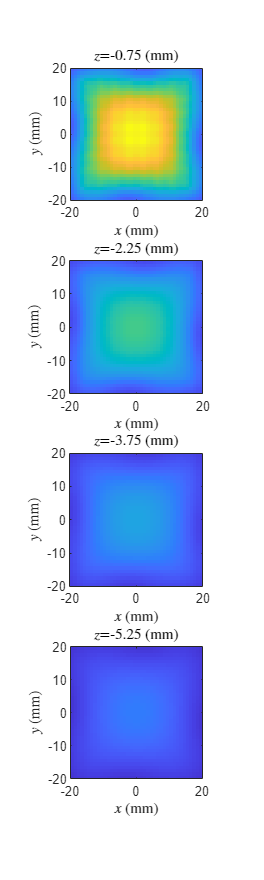

load('data\Sensitivity_100Hz_temp.mat')
VisualizeSensitivity(S, element_centers, 'all')

function S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size)

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
ComsolModel('SolveCoil', Model, Coil, freq, mesh_size);
E1 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    ComsolModel('SolveSensor', Model, Sensor, freq, mesh_size);
    E2 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

end

function S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq)

pos = Plate.gauss_points;
omega = 2*pi * freq;

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
[E1x,E1y] = CoilElectricField(pos(1,:,:), pos(2,:,:), pos(3,:,:));
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    [E2x,E2y] = SensorElectricField(pos(1,:,:), pos(2,:,:), pos(3,:,:));
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum((E1x.*E2x + E1y.*E2y) .* Plate.gauss_weights, 2);    
end

    function [Ex,Ey] = CoilElectricField(x,y,z)
        if ~isfield(Coil, 'model')
            if Coil.fillet ~= Coil.width / 2
                error('Only support cylindrical coil')
            end
            zc = unique(Coil.positions(3,:));
            if numel(zc) ~= 1
                error('Coils must be at the same z position')
            end
            r2 = Coil.width / 2;
            r1 = r2 - Coil.thickness;
            z2 = zc + Coil.height / 2;
            z1 = zc - Coil.height / 2;
            N = Coil.N_turns;
            sigma = Plate.conductivity;
            mur = Plate.relative_permeability;
            d = Plate.height;
            
            Coil.model = CoilAbovePlate(r1,r2,z1,z2,N, sigma,mur,d);
        end

        Ex = zeros(size(x));
        Ey = zeros(size(x));
        for z_layer = reshape(unique(z), 1,[])
            mask = z == z_layer;
            for p = 1:size(Coil.positions,2)
                [theta,r] = cart2pol(x(mask)-Coil.positions(1,p), y(mask)-Coil.positions(2,p));
                E_theta = Coil.model.E_theta(r,z(mask), omega) * Coil.current(p);
                Ex(mask) = Ex(mask) + E_theta .* -sin(theta);
                Ey(mask) = Ey(mask) + E_theta .*  cos(theta);
            end
        end
    end

    function [Ex,Ey] = SensorElectricField(x,y,z)
        if ~isfield(Sensor, 'model')
            Sensor.model = {};
        end
        p = Sensor.compute_index;
        if length(Sensor.model) < p || isempty(Sensor.model{p})
            sigma = Plate.conductivity;
            mur = Plate.relative_permeability;
            d = Plate.height;
            Sensor.model{p} = SensorAbovePlate(Sensor.positions(3,p), Sensor.axes(:,p), sigma,mur,d);
        end

        Ex = zeros(size(x));
        Ey = zeros(size(x));
        for z_layer = reshape(unique(z), 1,[])
            mask = z == z_layer;
            [Ex(mask),Ey(mask)] = Sensor.model{p}.E( ...
                x(mask)-Sensor.positions(1,p), y(mask)-Sensor.positions(2,p), z(mask), omega);
        end
    end

end

function VisualizeSensitivity(S, element_centers, varargin)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

if isempty(varargin) || strcmpi(varargin{1}, 'all')
    S_norm = vecnorm(S);
else
    S_norm = abs(S(varargin{1},:));
end

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    x = minmax(element_centers(1,mask)) * scale;
    y = minmax(element_centers(2,mask)) * scale;

    subplot(length(z),1,k)
    imagesc(x, y, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end